# Estimation of stress-dependent properties of  DR01_54_HTI sample

**Author**: Abakumov Ivan, Martin Rühlmann

**Publication date**: 18th July 2019

**E-mail**: abakumov_ivan@mail.ru

## Introduction

## Add MLIB library

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## Measurements on Aluminium sample 

Upload the data: 

5 independent measurements in 2 different directions

ALdata = zeros(10,10000);

for ii = 1:10
    filename = ['/home/ivan/Desktop/Martin/Stress_measurements/Alu_calibration/vor/org/tek' mynum2str(ii,4) 'CH2.csv'];
    data = read_csv_files(filename,15,10014);
    ALdata(ii,:) = data(:,2);
    tt = data(:,1);
end
dt = tt(2) - tt(1);

% for ii = 1:10
%     filename = ['/home/ivan/Desktop/Martin/Stress_measurements/Alu_calibration/danach/org/tek' mynum2str(ii,4) 'CH2.csv'];
%     data = read_csv_files(filename,15,10014);
%     ALdatam(ii,:) = data(:,2);
%     tt = data(:,1);
% end

dterr = 2*1.5e-08;  % sec
dverr = 2*12.5;     % m/sec

Amplitude normalization

for ii = 1:10
    ALdata(ii,:) = ALdata(ii,:)/max(ALdata(ii,:)); 
end

Clip first arrival signal

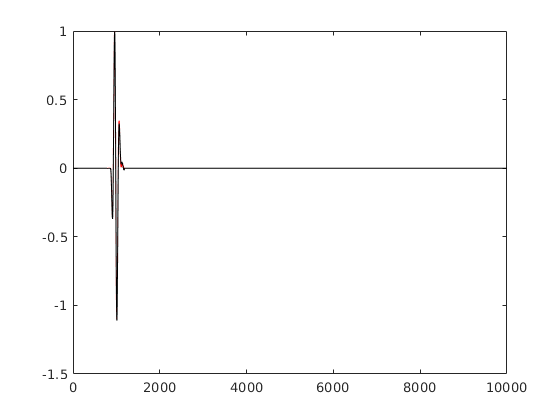

for ii = 1:10
    trace = ALdata(ii,:);
    [~,imax] = max(trace);
    [~,imin] = min(trace);
    indc = round((imax+imin)/2);
    ind = (indc-200):(indc+200);
    ntrace = zeros(size(trace));
    ntrace(ind) = trace(ind)-0.005; 
    ALdata(ii,:) = ntrace;
end

figure(1343)
plot(ALdata(1:5,:)', 'r')
hold on
plot(ALdata(6:10,:)', 'k')


trace_ref = sum(ALdata(1:5,:))/5;

Find the absolute traveltime of the signal on reference trace:

[~,imax] = max(trace_ref);
Tref = tt(imax);
Tcor = 173.69*dt;
Lref = 0.050;
Val = Lref/(Tref - Tcor);
disp(['Val = ' num2str(Val) ' (should be equal 6.375 km/s)'])

Val = 6375.0303 (should be equal 6.375 km/s)


## Upload measurements on DR01_HTI sample 

Sigma = [0 2 5 7.5 10 15 20 25 30 35];
Alfa = [20 170 160 70 130 0 40 30 90 80 180 100 150 140 110 120 50 60 10 ... 
        110 120 30 170 150 50 130 10 60 100 20 70 40 160 140 80 180 90 0]; 

Data = zeros(length(Sigma),length(Alfa),10000);

for i = 1:length(Sigma)
    for j = 1:length(Alfa)
        ii = j + (i-1)*length(Alfa);
        filename = ['/home/ivan/Desktop/Martin/Stress_measurements/DR01_HTI_ser4/org/tek' mynum2str(ii,4) 'CH2.csv'];
        data = read_csv_files(filename,15,10014);
        Data(i,j,:) = data(:,2);
        tt = data(:,1);
    end
end

Amplitude normalization

AMP = zeros(length(Sigma),length(Alfa));
nData = Data; 
for i = 1:length(Sigma)
    for j = 1:length(Alfa)
        AMP(i,j) = max(abs(hilbert(Data(i,j,:))));
        nData(i,j,:) = Data(i,j,:)/max(Data(i,j,:)); 
    end
end

Clip first arrival signal

cData = zeros(size(nData)); 

for i = 1:length(Sigma)
    for j = 1:length(Alfa)
        trace = nData(i,j,:);
        [~,imax] = max(trace);
        [~,imin] = min(trace);
        indc = round((imax+imin)/2);
        ind = (indc-200):(indc+200);
        cData(i,j,ind) = nData(i,j,ind)-0.01; 
    end
end

## Find timeshifts

DT = zeros(length(Sigma),length(Alfa));
CC = zeros(length(Sigma),length(Alfa));
dt = tt(2)-tt(1);

Find timeshifts between the reference trace and all other traces

for i = 1:length(Sigma)
    for j = 1:length(Alfa)

        trace = squeeze(cData(i,j,:));

        [DT(i,j),CC(i,j)] = mycorr_hilbert(trace_ref, trace, dt);
    end
end

Find phase rotation

for i = 1:length(Sigma)
    for j = 1:length(Alfa)

        trace = squeeze(cData(i,j,:));
        
        tracesh = add_time_shift_fft(trace,-DT(i,j),1/dt);
        
        mcc = 0; 
        for phaselag = 0:0.01:pi/2
            trace_lag = add_phase_rotation(tracesh, phaselag);
            cc = trace_ref*trace_lag/norm(trace_lag)/norm(trace_ref);
            if mcc < cc
                PP(i,j) = phaselag; 
                MCC(i,j) = cc;
                mcc = cc;
            end
        end

    end
end

Sort measurements with increasing angles

[AlfaS, ind] = sort(Alfa); 

DT = DT(:,ind); 
CC  = CC(:,ind); 
AMP = AMP(:,ind);
PP = PP(:,ind);

Make manual correction of outliers.

Note: the error is in the measurements, not in the cross-correlation procedure

DT(1,36) = DT(1,35);
DT(9,6) = DT(9,5);
DT(5,7) = DT(5,8);

Find absolute traveltiems

TT = DT + Tref;

Make traveltime correction

%Tcor = 211*dt;
TT = TT - Tcor;

Length of the sample 50 mm

Radial deformation of the sample:  $100\;\frac{\mu m}{m\;\mathrm{MPa}}$ 

Max radial deformation: 100*35*0.05 = 175 mum = 0.175 mm

L = 0.050;
[ALFAS, SIGMA] = meshgrid(AlfaS,Sigma);
dL = 100*L*SIGMA*1e-6;      
LL = L + dL; 

Find phase velocities:

V = LL./(TT);

Plot the results:

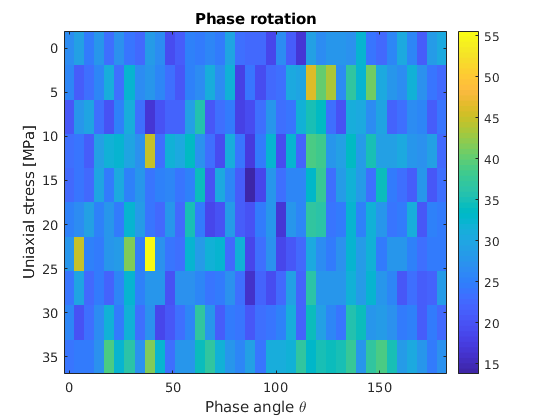

figure(21)
imagesc(AlfaS, Sigma, PP/pi*180)
title('Phase rotation')
ylabel('Uniaxial stress [MPa]')
xlabel('Phase angle \theta')
colorbar

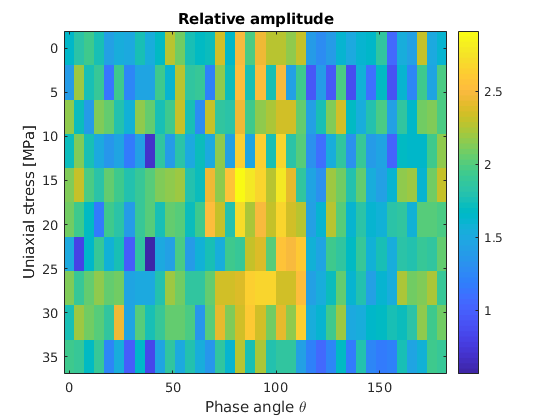


figure(22)
imagesc(AlfaS, Sigma, AMP)
title('Relative amplitude')
ylabel('Uniaxial stress [MPa]')
xlabel('Phase angle \theta')
colorbar

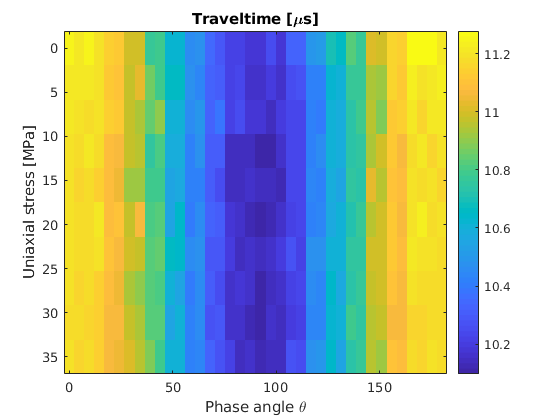


figure(23)
imagesc(AlfaS, Sigma, TT*1e6)
title('Traveltime [\mus]')
ylabel('Uniaxial stress [MPa]')
xlabel('Phase angle \theta')
colorbar

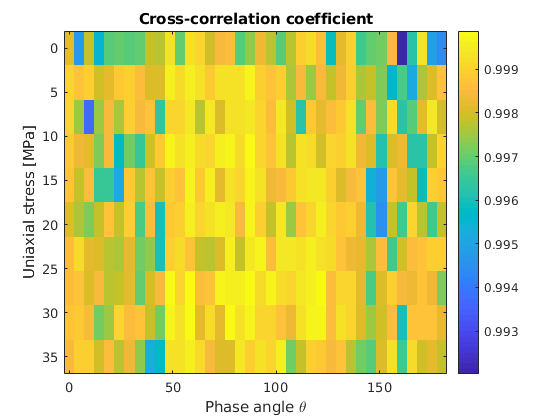


figure(24)
imagesc(AlfaS, Sigma, CC)
title('Cross-correlation coefficient')
ylabel('Uniaxial stress [MPa]')
xlabel('Phase angle \theta')
colorbar

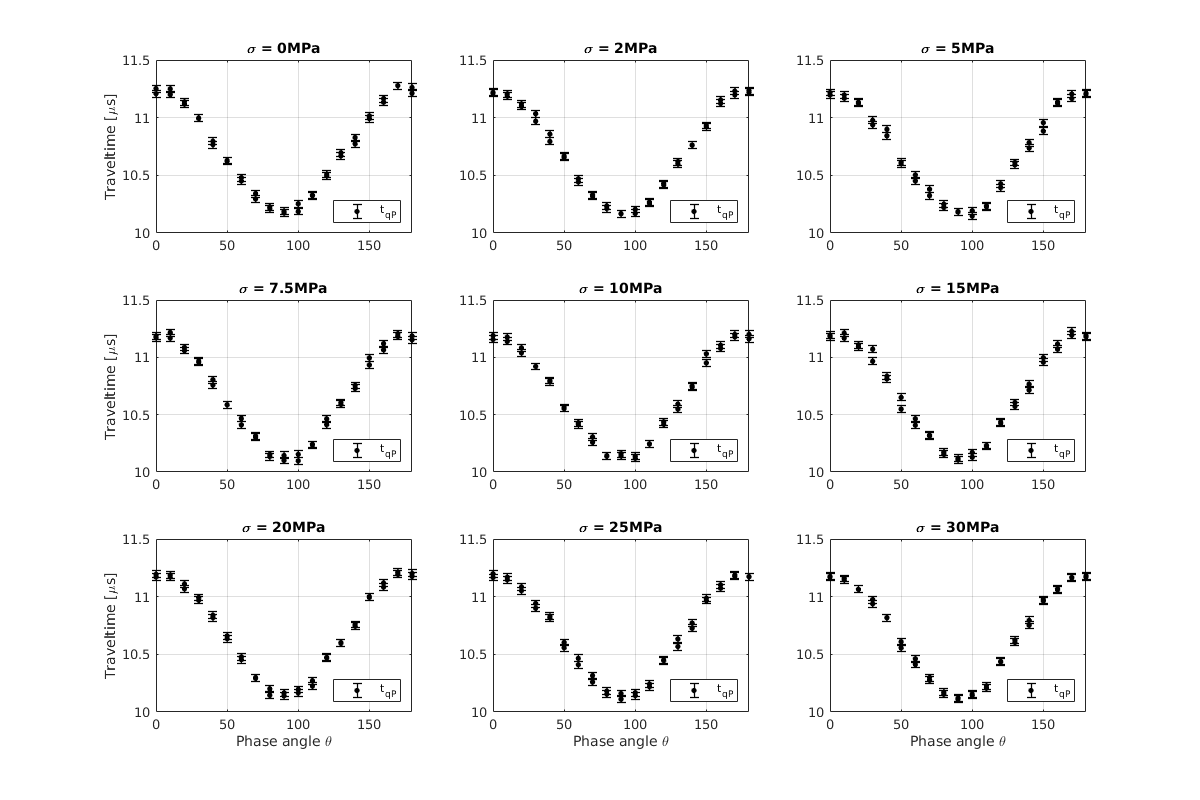


figure(25)
fig = figure('Position', [1 1 1200 800]);
for i = 1:9
    subplot(3,3,i)
    x_data = AlfaS;
    y_data = TT(i,:)*1e6;
    err_data = (dterr*1e6)*ones(size(y_data));
    errorbar(x_data,y_data,err_data,'.', 'Color','black','LineWidth',1,'MarkerSize',12);
    hold on
    l= legend('t_{qP}');
    l.Location = 'southeast';
    axis([0 180 10 11.5])
    grid on
    title(['\sigma = ' num2str(Sigma(i)) 'MPa'])
    if i>6
        xlabel('Phase angle \theta')
    end
    if mod(i-1,3)==0
        ylabel('Traveltime [\mus]')
    end
end

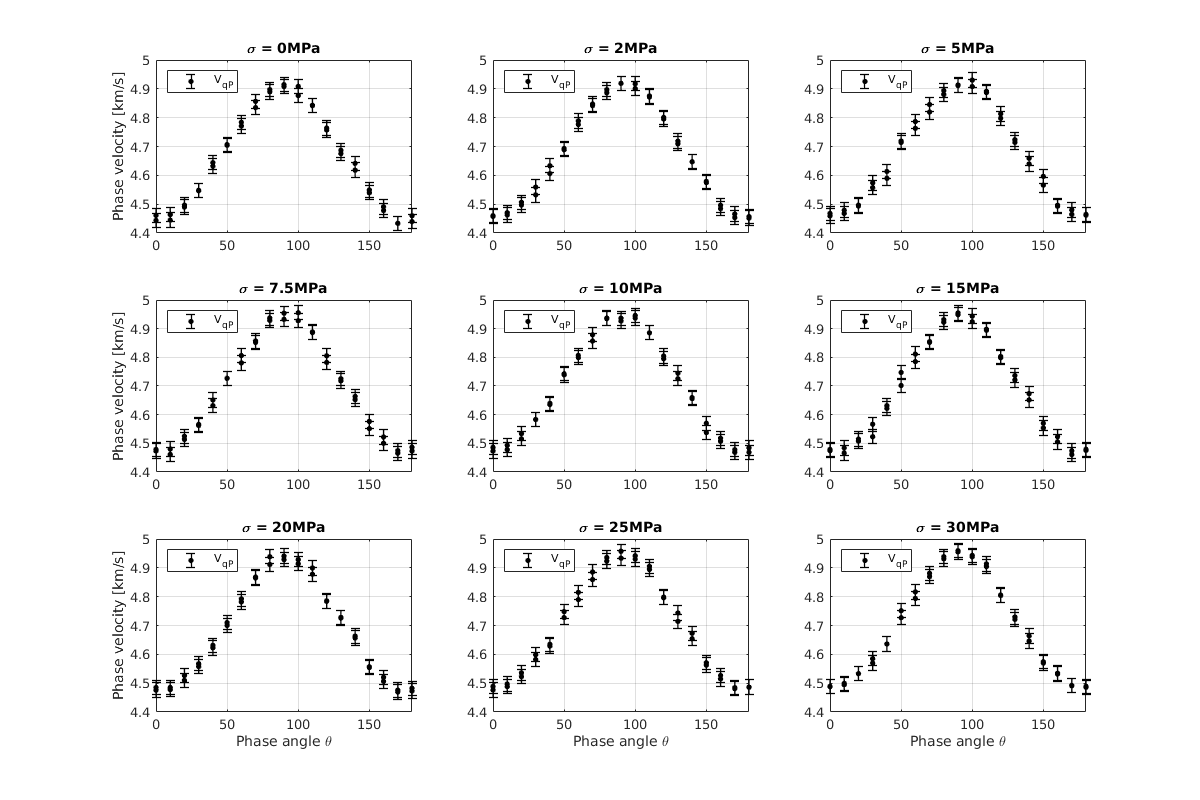


figure(26)
fig = figure('Position', [1 1 1200 800]);
for i = 1:9
    subplot(3,3,i)
    x_data = AlfaS;
    y_data = V(i,:)/1000;
    err_data = (dverr/1000)*ones(size(y_data));
    errorbar(x_data,y_data,err_data,'.', 'Color','black','LineWidth',1,'MarkerSize',12);
    hold on
    l= legend('V_{qP}');
    l.Location = 'northwest';
    axis([0 180 4.4 5.0])
    grid on
    title(['\sigma = ' num2str(Sigma(i)) 'MPa'])
    if i>6
        xlabel('Phase angle \theta')
    end
    if mod(i-1,3)==0
        ylabel('Phase velocity [km/s]')
    end
end

## Find the best-fit parameters

Alpha   = linspace(4400,4630,101);
Delta   = linspace(0.05,0.15,51);
Epsilon = linspace(0.10,0.12,21);
dTheta  = linspace(-2.5,2.5,11);
%dTheta  = -0.35;

for i = 1:length(Sigma)

    Vqp = V(i,:);

    Sample.Vqp = Vqp; 
    Sample.Theta = AlfaS; 

    J = costFunction_delta_weak(Sample,Alpha,Delta,Epsilon,dTheta);

    [~, ind] = min(J(:));
    [inda,indd,inde,indt] = ind2sub(size(J),ind);

    result.alpha(i) = Alpha(inda);
    result.delta(i) = Delta(indd);
    result.epsilon(i) = Epsilon(inde);
    result.dtheta(i) = dTheta(indt);
end

## Plot the result:

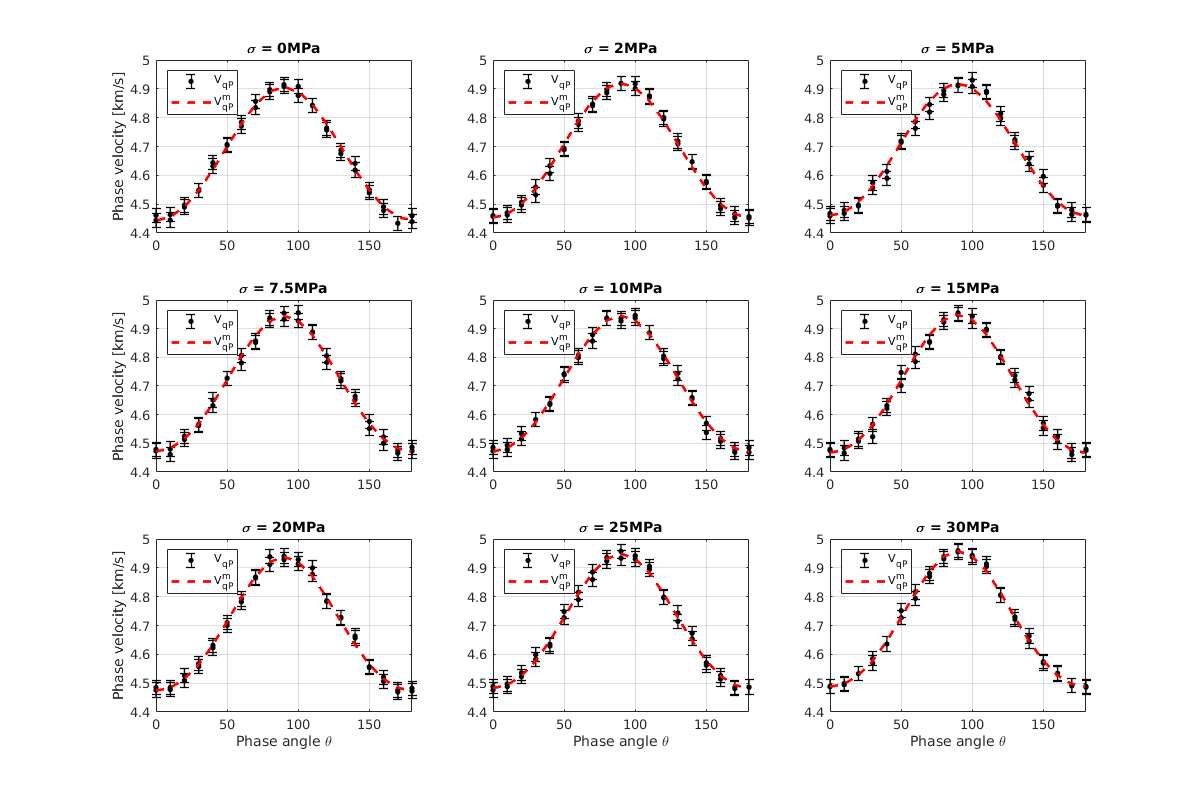

figure(27)
fig = figure('Position', [1 1 1200 800]);

for i =1:length(Sigma)

    Vqp = V(i,:);
    Sample.Vqp = Vqp; 
    Sample.Theta = AlfaS; 
    
    alpha = result.alpha(i);
    delta = result.delta(i);
    epsilon = result.epsilon(i);
    dtheta = result.dtheta(i);
    
    Vqp = get_Vqp_VTI_weak(Sample,alpha,delta,epsilon,dtheta);
 
    if i~=10
        subplot(3,3,i)
        x_data = AlfaS;
        y_data = V(i,:)/1000;
        err_data = (dverr/1000)*ones(size(y_data));
        errorbar(x_data,y_data,err_data,'.', 'Color','black','LineWidth',1,'MarkerSize',12);
        hold on
        plot(Sample.Theta+dtheta, Vqp/1000, 'r--','LineWidth',2)
        l=legend('V_{qP}','V_{qP}^m');
        l.Location = 'northwest';
        axis([0 180 4.4 5.0])
        grid on
        title(['\sigma = ' num2str(Sigma(i)) 'MPa'])
        if i>6
            xlabel('Phase angle \theta')
        end
        if mod(i-1,3)==0
            ylabel('Phase velocity [km/s]')
        end
    end
end

## Find errors of estimated parameters

% angle error std: 3 grad  =>> error in velocity 25 m/s
% error in velocity due to measurements =>> 15 m/s
% total error: 30 m 
%                                     37 mrasurement 73
% variance for velocity error 30 m = 0.010;   0.0060
% variance for velocity error 100 m = 0.030   0.020

alpha = mean(result.alpha);
delta = mean(result.delta);
epsilon = mean(result.epsilon);
dtheta = mean(result.dtheta);

Theta = 0:10:360;

clear test; 

for i=1:1:100

    Sample.Theta = Theta + 1*randn(size(Theta));
    Vqptrue = get_Vqp_VTI_weak(Sample,alpha,delta,epsilon,dtheta);

    VqpE = Vqptrue+12.5*randn(1,37);
    Sample.Vqp = VqpE; 
    Sample.Theta = Theta; 

    J = costFunction_delta_weak(Sample,Alpha,Delta,Epsilon,dTheta);

    [~, ind] = min(J(:));
    [inda,indd,inde,indt] = ind2sub(size(J),ind);

    test.alpha(i) = Alpha(inda);
    test.delta(i) = Delta(indd);
    test.epsilon(i) = Epsilon(inde);
    test.dtheta(i) = dTheta(indt);
end

## Plot results:

figure(33)
subplot(2,2,1); 
histfit(test.alpha',11)
xlabel('V_{P0}, [m/s]')
dist = fitdist(test.alpha(1:100)','Normal');
disp(['ALPHA: Relative error: ' num2str(abs(alpha-dist.mu)/alpha*100) '%'])

ALPHA: Relative error: 0.014408%


alpha_err = 2*dist.sigma; 
title(['\mu=' num2str(dist.mu,4) ' \sigma=' num2str(dist.sigma,2)])

subplot(2,2,2); 
histfit(test.delta',11)
xlabel('\delta')
dist = fitdist(test.delta(1:100)','Normal');
disp(['DELTA: Relative error: ' num2str(abs(delta-dist.mu)/delta*100) '%'])

DELTA: Relative error: 0.46914%


delta_err = 2*dist.sigma; 
title(['\mu=' num2str(dist.mu,2) ' \sigma=' num2str(dist.sigma,2)])

subplot(2,2,3); 
histfit(test.epsilon',11)
xlabel('\epsilon')
dist = fitdist(test.epsilon(1:100)','Normal');
disp(['EPSILON: Relative error: ' num2str(abs(epsilon-dist.mu)/epsilon*100) '%'])

EPSILON: Relative error: 0.35305%


epsilon_err = 2*dist.sigma; 
title(['\mu=' num2str(dist.mu,2) ' \sigma=' num2str(dist.sigma,2)])
%
subplot(2,2,4); 
histfit(test.dtheta',11)
xlabel('\Delta\theta')
dist = fitdist(test.dtheta(1:100)','Normal');
disp(['DTHETA: Absolute error: ' num2str(dtheta-dist.mu)])

DTHETA: Absolute error: -0.075


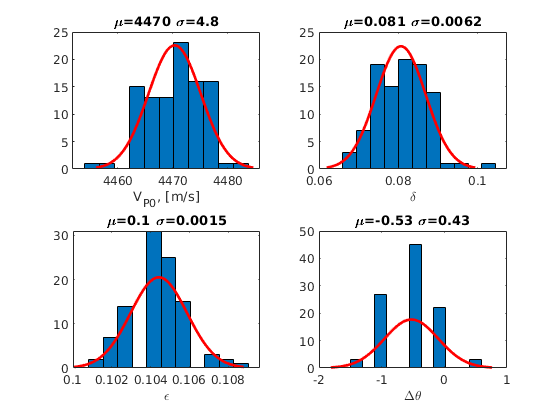

dtheta_err = 2*dist.sigma; 
title(['\mu=' num2str(dist.mu,2) ' \sigma=' num2str(dist.sigma,2)])

## Plot results and make interpolation

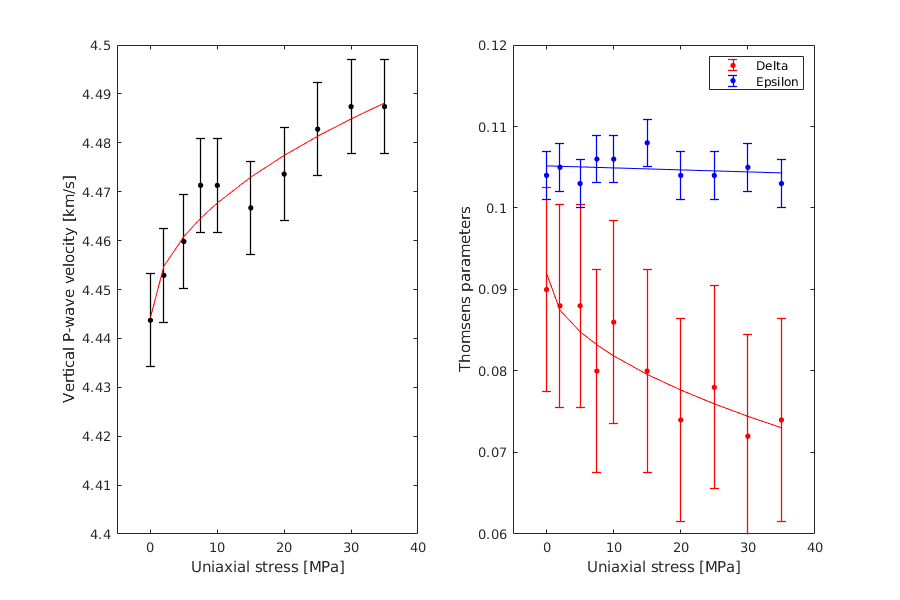

X = ones(10,4);
X(:,2) = Sigma;
X(:,3) = Sigma.^2;
X(:,4) = Sigma.^3;
X(:,5) = sqrt(Sigma);
X1 = X(:,1:2);
X2 = X(:,1:3);
X3 = X(:,[1,5]);
malpha = X3*inv(X3'*X3)*X3'*result.alpha';
mdelta = X3*inv(X3'*X3)*X3'*result.delta';
mepsilon = X1*inv(X1'*X1)*X1'*result.epsilon';
     
     
figure(313)
fig = figure('Position', [1 1 900 600]);
subplot(1,2,1)
x_data = Sigma;
y_data = result.alpha/1000;
err_data = (alpha_err/1000)*ones(size(y_data));
errorbar(x_data,y_data,err_data,'.', 'Color','black','LineWidth',1,'MarkerSize',12);
hold on 
plot(Sigma,malpha/1000, '-r')
xlabel('Uniaxial stress [MPa]')
ylabel('Vertical P-wave velocity [km/s]')
axis([-5 40 4.4, 4.5])
subplot(1,2,2)
x_data = Sigma;
y_data = result.delta;
err_data = (delta_err)*ones(size(y_data));
errorbar(x_data,y_data,err_data,'.', 'Color','red','LineWidth',1,'MarkerSize',12);
hold on 
x_data = Sigma;
y_data = result.epsilon;
err_data = (epsilon_err)*ones(size(y_data));
errorbar(x_data,y_data,err_data,'.', 'Color','blue','LineWidth',1,'MarkerSize',12);
plot(Sigma,mdelta, '-r');
plot(Sigma,mepsilon, '-b');
axis([-5 40 0.06, 0.12])
legend('Delta','Epsilon')
xlabel('Uniaxial stress [MPa]')
ylabel('Thomsens parameters')